# Estudio de **cambios de fase**

clf;clc;clear all
load("MatricesSparse.mat")
load("Nodos.mat")
load("Data_CGs.mat")
load("Analisis_GC.mat") 

## **Conexion entre CG de Alemania y Francia  AF**

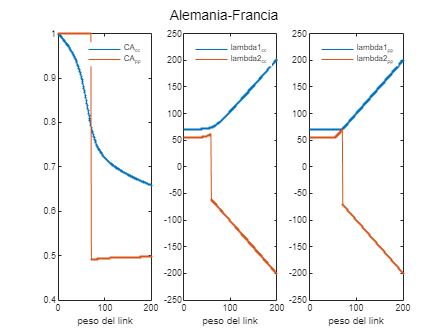

minpeso = 1;
maxpeso = 200;

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AF_CC(minpeso:maxpeso),'.-')
hold on
plot(minpeso:maxpeso,plotCA_AF_PP(minpeso:maxpeso),'.-')
xlabel('peso del link')
 
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AF_CC(minpeso:maxpeso),'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_CC(minpeso:maxpeso),'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AF_PP(minpeso:maxpeso),'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_PP(minpeso:maxpeso),'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Alemania-Francia')

### Plots de C_A_CC y C_A_PP de todas las combinaciones

Pesos para el tamaño de los plots

minpeso = 1;
maxpeso = 150;

CA_cc de todas las combinaciones de conexiones:

figure 
plot(minpeso:maxpeso,plotCA_AF_CC(minpeso:maxpeso),'o-')
hold ;

Current plot held


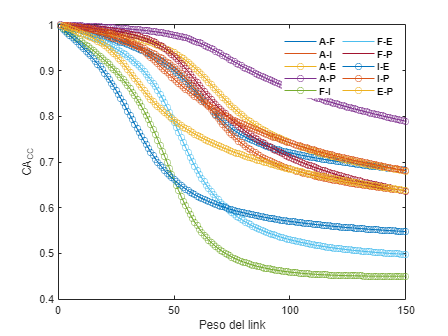

plot(minpeso:maxpeso,plotCA_AI_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AE_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AP_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FI_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FE_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FP_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_IE_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_IP_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_EP_CC(minpeso:maxpeso),'o-')
xlabel("Peso del link")
ylabel("CA_{CC}")
legend({'A-F','A-I','A-E','A-P','F-I','F-E','F-P','I-E','I-P','E-P'},...
    'Location','northeast','NumColumns',2,'Box','off','FontWeight','bold');
hold off

CA_pp de todas las combinaciones de conexiones:

figure 
plot(minpeso:maxpeso,plotCA_AF_PP(minpeso:maxpeso),'o-')
hold ;

Current plot held


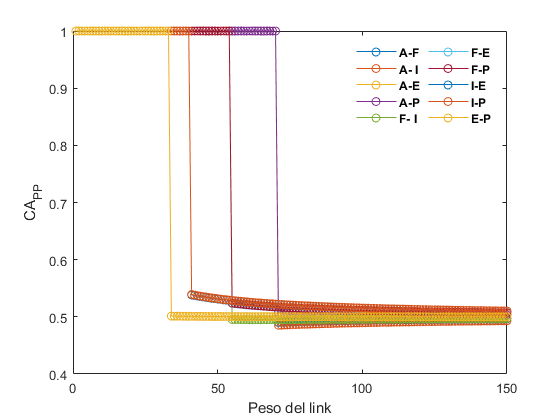

plot(minpeso:maxpeso,plotCA_AI_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AE_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AP_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FI_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FE_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FP_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_IE_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_IP_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_EP_PP(minpeso:maxpeso),'o-')
xlabel("Peso del link")
ylabel("CA_{PP}")
legend({'A-F','A- I','A-E','A-P','F- I','F-E','F-P','I-E','I-P','E-P'},...
    'Location','northeast','NumColumns',2,'Box','off','FontWeight','bold');
hold off

### Creacion de tablas para la comparacion de las diferentes conexiones de Componentes Gigantes CON PESO DE LINK = 1

load("Var_Archivo_3_TFG.mat")

#### CA_cc

Details = [0,CA_AF_CC,CA_AI_CC,CA_AE_CC,CA_AP_CC; ...
    0,0,CA_FI_CC,CA_FE_CC,CA_FP_CC;...
    0,0,0,CA_IE_CC,CA_IP_CC;...
    0,0,0,0,CA_EP_CC];
T = array2table(Details,...
    'VariableNames',{'Ale';'Fra';'Ita';'Esp';'Por'},...
     'RowNames',{'Ale';'Fra';'Ita';'Esp'}); 
T = table(T,'VariableNames',{'CA_{cc}'}); % Nested table
disp(T)

                           CA_{cc}                        
           Ale      Fra        Ita        Esp        Por  
    ______________________________________________________

    Ale     0     0.99875    0.99888    0.99929    0.99975
    Fra     0           0    0.99633    0.99822    0.99953
    Ita     0           0          0    0.99535    0.99937
    Esp     0           0          0          0    0.99829



#### CA_pp

Details = [0,CA_AF_PP,CA_AI_PP,CA_AE_PP,CA_AP_PP; ...
    0,0,CA_FI_PP,CA_FE_PP,CA_FP_PP;...
    0,0,0,CA_IE_PP,CA_IP_PP;...
    0,0,0,0,CA_EP_PP];
T = array2table(Details,...
    'VariableNames',{'Ale';'Fra';'Ita';'Esp';'Por'},...
     'RowNames',{'Ale';'Fra';'Ita';'Esp'}); 
T = table(T,'VariableNames',{'CA_{PP}'}); % Nested table
disp(T)

                   CA_{PP}                
           Ale    Fra    Ita    Esp    Por
    ______________________________________

    Ale     0      1      1      1      1 
    Fra     0      0      1      1      1 
    Ita     0      0      0      1      1 
    Esp     0      0      0      0      1 



#### Mayor Autovalor CC

Mayor Autovalor de la red conjunta al conectar los nodos centrales mediante un nodo de peso 1

Details = [0,aut1_AF_CC,aut1_AI_CC,aut1_AE_CC,aut1_AP_CC; ...
    0,0,aut1_FI_CC,aut1_FE_CC,aut1_FP_CC;...
    0,0,0,aut1_IE_CC,aut1_IP_CC;...
    0,0,0,0,aut1_EP_CC];
T = array2table(Details,...
    'VariableNames',{'Ale';'Fra';'Ita';'Esp';'Por'},...
     'RowNames',{'Ale';'Fra';'Ita';'Esp'}); 
T = table(T,'VariableNames',{'Mayor Autovalor CC'}); % Nested table
disp(T)

                    Mayor Autovalor CC                
           Ale     Fra       Ita       Esp       Por  
    __________________________________________________

    Ale     0     70.202    70.202    70.202    70.202
    Fra     0          0    54.358    54.358    54.358
    Ita     0          0         0    40.446    40.446
    Esp     0          0         0         0    33.917



#### Mayor Autovalor PP

Mayor Autovalor de la red conjunta al conectar los nodos perifericos mediante un nodo de peso 1

Details = [0,aut1_AF_PP,aut1_AI_PP,aut1_AE_PP,aut1_AP_PP; ...
    0,0,aut1_FI_PP,aut1_FE_PP,aut1_FP_PP;...
    0,0,0,aut1_IE_PP,aut1_IP_PP;...
    0,0,0,0,aut1_EP_PP];
T = array2table(Details,...
    'VariableNames',{'Ale';'Fra';'Ita';'Esp';'Por'},...
     'RowNames',{'Ale';'Fra';'Ita';'Esp'}); 
T = table(T,'VariableNames',{'Mayor Autovalor PP'}); % Nested table
disp(T)

                    Mayor Autovalor PP                
           Ale     Fra       Ita       Esp       Por  
    __________________________________________________

    Ale     0     70.201    70.201    70.201    70.201
    Fra     0          0    54.358    54.358    54.358
    Ita     0          0         0    40.444    40.444
    Esp     0          0         0         0    33.916



## Obtención de las imágenes finales empleadas

load("MatricesSparse.mat")
load("Analisis_GC.mat")
load("Data_CGs.mat")
load("Nodos.mat")
load("Var_Archivo_3_TFG.mat")
load("Variables_Arch_2_TFG.mat")
%% Imagen 1
clf
figure
links_Ale = sum(sum(Ale_Colab))/2;
links_Fra = sum(sum(Fra_Colab))/2;
links_Ita = sum(sum(Ita_Colab))/2;
links_Esp = sum(sum(Esp_Colab))/2;
links_Por = sum(sum(Por_Colab))/2;
%links = sum(sum(SM_Colab))/2;
x = ["Ale" "Fra" "Ita" "Esp" "Por"];
y = [links_Ale 2835; links_Fra 1920; links_Ita 2593; links_Esp 1493; links_Por 247];
b = bar(log10(y),'BarWidth', 1);
b(1).FaceColor = [.2 .6 .5];
set(gca,'xticklabel',x, 'FontSize',18, 'Fontweight','bold')
legend({'\it E  ','\it N  '},'Location','NorthEast','FontWeight','normal','FontSize',24)
set(gcf,'color','w')
%% Imagen 2
clf
SM_Imagen4 = blkdiag(Ale_Colab,Fra_Colab,Ita_Colab,Esp_Colab,Por_Colab);
figure
tamanos_bloques = [size(Ale_Colab, 1), size(Fra_Colab, 1), size(Ita_Colab, 1), size(Esp_Colab, 1), size(Por_Colab, 1)];
limites_bloques = cumsum(tamanos_bloques);
subplot(1,2,1) %Super Matrix
spy(SM_Imagen4,'m');
hold on
spy(SM_Imagen4(1:limites_bloques(4),1:limites_bloques(4)),'r');
spy(SM_Imagen4(1:limites_bloques(3),1:limites_bloques(3)),'g');
spy(SM_Imagen4(1:limites_bloques(2),1:limites_bloques(2)),'b');
spy(SM_Imagen4(1:limites_bloques(1),1:limites_bloques(1)),'c');
axis([1 9088, 1 9088])
ylabel('Autor i', 'FontSize', 11)
xlabel('Autor j', 'FontSize', 11)
xticklabels(' ')
yticklabels(' ')
lgd = legend({'Por','Esp','Ita','Fra','Ale'},...
    'Location','northeast','NumColumns',2,'FontSize',12);
LimitsX = xlim; LimitsY = ylim;
title("(A)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)]);
hold off
subplot(1,2,2) %Grapico de alemania
plot(graph(Ale_Colab),'Layout', 'force')
axis off
title("(B)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [1, 1]);
set(gcf,'color','w')
%% Imagen 3 OPCION 1
% 4. La curva del fit no la haría hasta tomar valores por encima de diez a la cero. 
% Como es una curva que tú puedes manipular solo dibujaría el trozo de línea recta que es importante.
clf
figure
subplot(2,3,1)
p1 = loglog(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k-','LineWidth',1.25);
hold on
p2 = loglog(8:max(grados_Colab_S),((8:max(grados_Colab_S)).^(-gamma_S))*10^extra_S,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_S)+20 -10 100])
legend(p2,{['K^{-',num2str(gamma_S),'}',]},'Location','northeast','Box','off','FontSize',21);
title('SM','FontSize',19)
hold off
subplot(2,3,2)
p1 = loglog(1:max(grados_Colab_A_S),cdf_Colab_Ale_MAYOR,'c-','LineWidth',1.25);
hold on
p2 = loglog(6:max(grados_Colab_A_S),((6:max(grados_Colab_A_S)).^(-gamma_Ale))*10^extra_Ale,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_A_S)+20 0 100])
legend(p2,{['K^{-',num2str(gamma_Ale),'}',]},'Location','northeast','Box','off','FontSize',21);
title('Ale','FontSize',19)
hold off
subplot(2,3,3)
p1 = loglog(1:max(grados_Colab_F_S),cdf_Colab_Fra_MAYOR,'b-','LineWidth',1.25);
hold on
p2 = loglog(5:max(grados_Colab_F_S),((5:max(grados_Colab_F_S)).^(-gamma_Fra))*10^extra_Fra,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_F_S)+15 0 100])
legend(p2,{['K^{-',num2str(gamma_Fra),'}',]},'Location','northeast','Box','off','FontSize',21);
title('Fra','FontSize',19)
hold off
subplot(2,3,4)
p1 = loglog(1:max(grados_Colab_I_S),cdf_Colab_Ita_MAYOR,'g-','LineWidth',1.25);
hold on
p2 = loglog(5:max(grados_Colab_I_S),((5:max(grados_Colab_I_S)).^(-gamma_Ita))*10^extra_Ita,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_I_S)+15 0 100])
legend(p2,{['K^{-',num2str(gamma_Ita),'}',]},'Location','northeast','Box','off','FontSize',21);
title('Ita','FontSize',19)
hold off
subplot(2,3,5)
p1 = loglog(1:max(grados_Colab_E_S),cdf_Colab_Esp_MAYOR,'r-','LineWidth',1.25);
hold on
p2 = loglog(4:max(grados_Colab_E_S),((4:max(grados_Colab_E_S)).^(-gamma_Esp))*10^extra_Esp,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_E_S)+15 0 100])
legend(p2,{['K^{-',num2str(gamma_Esp),'}',]},'Location','northeast','Box','off','FontSize',21);
title('Esp','FontSize',19)
hold off
subplot(2,3,6)
p1 = loglog(1:max(grados_Colab_P_S),cdf_Colab_Por_MAYOR,'m-','LineWidth',1.25);
hold on
p2 = loglog(2:max(grados_Colab_P_S),((2:max(grados_Colab_P_S)).^(-gamma_Por))*10^extra_Por,'-');
xlabel('k','FontSize',19)
ylabel('P(K ≥ k)','FontSize',20)
set(gca, 'FontSize', 12) % Cambiar tamaño de las etiquetas de los ejes X e Y
axis([0 max(grados_Colab_P_S)+2 -10 100])
legend(p2,{['K^{-',num2str(gamma_Por),'}',]},'Location','northeast','Box','off','FontSize',21);
title('Por','FontSize',19)
hold off
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 4
clf
SM_Imagen4 = blkdiag(adj_GC_A,adj_GC_F,adj_GC_I,adj_GC_E,adj_GC_P);
figure
tamanos_bloques = [size(adj_GC_A, 1), size(adj_GC_F, 1), size(adj_GC_I, 1), size(adj_GC_E, 1), size(adj_GC_P, 1)];
limites_bloques = cumsum(tamanos_bloques);
subplot(1,2,1) %Super Matrix
spy(SM_Imagen4,'m');
hold on
spy(SM_Imagen4(1:limites_bloques(4),1:limites_bloques(4)),'r');
spy(SM_Imagen4(1:limites_bloques(3),1:limites_bloques(3)),'g');
spy(SM_Imagen4(1:limites_bloques(2),1:limites_bloques(2)),'b');
spy(SM_Imagen4(1:limites_bloques(1),1:limites_bloques(1)),'c');
axis([1 limites_bloques(5), 1 limites_bloques(5)])
% ylabel('Autor i', 'FontSize', 11)
xlabel(' ', 'FontSize', 11)
xticklabels(' ')
yticklabels(' ')
legend({'Por','Esp','Ita','Fra','Ale'},...
    'Location','northeast','NumColumns',2,'FontSize',11);
LimitsX = xlim; LimitsY = ylim;
title("(A)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)]);
hold off
axis off
subplot(1,2,2) %Grapico de GC alemania
plot(graph(adj_GC_A),'Layout', 'force3','NodeColor', 'c')
axis off
title("(B)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left','VerticalAlignment','baseline','Units','normalized', 'Position', [0, 0.1, 1]);
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 5 ALEMANIA FRANCIA CC
clf
A = adj_GC_A;
B = adj_GC_F;
% Crear grafos a partir de las matrices de adyacencia
GrafoA = graph(A);
GrafoB = graph(B);
figure
% Dibujar Grafo A
hA = plot(GrafoA, 'Layout', 'force', 'NodeColor', 'c');
hold on;
% Ajustar las posiciones de los nodos de Grafo A
pA = hA.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo A
pA(:,2) = hA.YData';
% Dibujar Grafo B
hB = plot(GrafoB, 'Layout', 'force', 'NodeColor', 'b');
% Ajustar las posiciones de los nodos de Grafo B para que no se superpongan con Grafo A
hB.XData = hB.XData + max(hA.XData) + 5;
% Actualizar las posiciones de Grafo B
pB = hB.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo B
pB(:,2) = hB.YData';
% Especificar los nodos entre los que se desea dibujar la arista roja
nodeA = Central_node_A;  % Nodo en Grafo A
nodeB = Central_node_F;  % Nodo en Grafo B
% Coordenadas de los nodos especificados
x = [pA(nodeA, 1), pB(nodeB, 1)];
y = [pA(nodeA, 2), pB(nodeB, 2)];
% Dibujar la arista roja entre los nodos especificados de Grafo A y Grafo B
line(x, y, 'Color', 'k', 'LineWidth', 2);
% Añadir la anotación encima de la arista
midX = mean(x);
midY = mean(y);
text(midX, midY+0.25, 'Conexión CC', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'k');
% Ajustar la visualización
legend([hA,hB],{'Ale','Fra'},'Location','northeast','FontSize',13);
axis equal;
axis off;
hold off;
LimitsX = xlim; LimitsY = ylim;
title("(A)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)-5]);
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 5 Alemania Francia PP
clf
A = adj_GC_A;
B = adj_GC_F;
% Crear grafos a partir de las matrices de adyacencia
GrafoA = graph(A);
GrafoB = graph(B);
figure
% Dibujar Grafo A
hA = plot(GrafoA, 'Layout', 'force', 'NodeColor', 'c');
hold on;
% Ajustar las posiciones de los nodos de Grafo A
pA = hA.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo A
pA(:,2) = hA.YData';
% Dibujar Grafo B
hB = plot(GrafoB, 'Layout', 'force', 'NodeColor', 'b');
% Ajustar las posiciones de los nodos de Grafo B para que no se superpongan con Grafo A
hB.XData = hB.XData + max(hA.XData) + 5;
% Actualizar las posiciones de Grafo B
pB = hB.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo B
pB(:,2) = hB.YData';
% Especificar los nodos entre los que se desea dibujar la arista roja
nodeA = Peripheral_node_A;  % Nodo en Grafo A
nodeB = Peripheral_node_F;  % Nodo en Grafo B
% Coordenadas de los nodos especificados
x = [pA(nodeA, 1), pB(nodeB, 1)];
y = [pA(nodeA, 2), pB(nodeB, 2)];
% Dibujar la arista roja entre los nodos especificados de Grafo A y Grafo B
line(x, y, 'Color', 'k', 'LineWidth', 2);
% Añadir la anotación encima de la arista
midX = mean(x);
midY = mean(y);
text(midX, midY+0.25, 'Conexión PP', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'k');
% Ajustar la visualización
legend([hA,hB],{'Ale','Fra'},'Location','northeast','FontSize',13);
axis equal;
axis off;
hold off;
LimitsX = xlim; LimitsY = ylim;
title("(B)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)-5]);
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 5 ALEMANIA ESPAÑA CC
clf
A = adj_GC_A;
B = adj_GC_E;
% Crear grafos a partir de las matrices de adyacencia
GrafoA = graph(A);
GrafoB = graph(B);
figure
% Dibujar Grafo A
hA = plot(GrafoA, 'Layout', 'force', 'NodeColor', 'c');
hold on;
% Ajustar las posiciones de los nodos de Grafo A
pA = hA.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo A
pA(:,2) = hA.YData';
% Dibujar Grafo B
hB = plot(GrafoB, 'Layout', 'force', 'NodeColor', 'r');
% Ajustar las posiciones de los nodos de Grafo B para que no se superpongan con Grafo A
hB.XData = hB.XData + max(hA.XData) + 7;
% Actualizar las posiciones de Grafo B
pB = hB.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo B
pB(:,2) = hB.YData';
% Especificar los nodos entre los que se desea dibujar la arista roja
nodeA = Central_node_A;  % Nodo en Grafo A
nodeB = Central_node_E;  % Nodo en Grafo B
% Coordenadas de los nodos especificados
x = [pA(nodeA, 1), pB(nodeB, 1)];
y = [pA(nodeA, 2), pB(nodeB, 2)];
% Dibujar la arista roja entre los nodos especificados de Grafo A y Grafo B
line(x, y, 'Color', 'k', 'LineWidth', 2);
% Añadir la anotación encima de la arista
midX = mean(x);
midY = mean(y);
text(midX, midY+0.25, 'Conexión CC', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'k');
% Ajustar la visualización
legend([hA,hB],{'Ale','Esp'},'Location','northeast','FontSize',13);
axis equal;
axis off;
hold off;
LimitsX = xlim; LimitsY = ylim;
title("(A)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)-5]);
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 5 Alemania España PP
clf
A = adj_GC_A;
B = adj_GC_E;
% Crear grafos a partir de las matrices de adyacencia
GrafoA = graph(A);
GrafoB = graph(B);
figure
% Dibujar Grafo A
hA = plot(GrafoA, 'Layout', 'force', 'NodeColor', 'c');
hold on;
% Ajustar las posiciones de los nodos de Grafo A
pA = hA.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo A
pA(:,2) = hA.YData';
% Dibujar Grafo B
hB = plot(GrafoB, 'Layout', 'force', 'NodeColor', 'r');
% Ajustar las posiciones de los nodos de Grafo B para que no se superpongan con Grafo A
hB.XData = hB.XData + max(hA.XData) + 7;
% Actualizar las posiciones de Grafo B
pB = hB.XData' + 0; % Obtener las posiciones generadas automáticamente para Grafo B
pB(:,2) = hB.YData';
% Especificar los nodos entre los que se desea dibujar la arista roja
nodeA = Peripheral_node_A;  % Nodo en Grafo A
nodeB = Peripheral_node_E;  % Nodo en Grafo B
% Coordenadas de los nodos especificados
x = [pA(nodeA, 1), pB(nodeB, 1)];
y = [pA(nodeA, 2), pB(nodeB, 2)];
% Dibujar la arista roja entre los nodos especificados de Grafo A y Grafo B
line(x, y, 'Color', 'k', 'LineWidth', 2);
% Añadir la anotación encima de la arista
midX = mean(x);
midY = mean(y);
text(midX, midY+0.25, 'Conexión PP', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Color', 'k');
% Ajustar la visualización
legend([hA,hB],{'Ale','Esp'},'Location','northeast','FontSize',13);
axis equal;
axis off;
hold off;
LimitsX = xlim; LimitsY = ylim;
title("(B)",'FontWeight',"bold",'FontSize',11,'HorizontalAlignment', 'left', 'position', [LimitsX(1), LimitsY(2)-5]);
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 6 TODOS
minpeso = 1;
maxpeso = 150;
clf
figure
subplot(2,1,1)
plot(minpeso:maxpeso,plotCA_AF_CC(minpeso:maxpeso),'o-')
hold ;
plot(minpeso:maxpeso,plotCA_AI_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AE_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AP_CC(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FI_CC(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_FE_CC(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_FP_CC(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_IE_CC(minpeso:maxpeso),'^-')
plot(minpeso:maxpeso,plotCA_IP_CC(minpeso:maxpeso),'^-')
plot(minpeso:maxpeso,plotCA_EP_CC(minpeso:maxpeso),'diamond-')
xlabel('ω','FontSize',21)
ylabel("C_{A  cc}",'FontSize',28,'FontWeight','bold')
set(gca, 'FontSize', 15) % Cambiar tamaño de las etiquetas de los ejes X e Y
% legend({'Ale-Fra','Ale-Ita','Ale-Esp','Ale-Por','Fra-Ita','Fra-Esp','Fra-Por','Ita-Esp','Ita-Por','Esp-Por'},...
%     'Location','northeast','NumColumns',2,'Box','off','FontSize',13);
hold off

subplot(2,1,2)
plot(minpeso:maxpeso,plotCA_AF_PP(minpeso:maxpeso),'o-')
hold ;
plot(minpeso:maxpeso,plotCA_AI_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AE_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_AP_PP(minpeso:maxpeso),'o-')
plot(minpeso:maxpeso,plotCA_FI_PP(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_FE_PP(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_FP_PP(minpeso:maxpeso),'s-')
plot(minpeso:maxpeso,plotCA_IE_PP(minpeso:maxpeso),'^-')
plot(minpeso:maxpeso,plotCA_IP_PP(minpeso:maxpeso),'^-')
plot(minpeso:maxpeso,plotCA_EP_PP(minpeso:maxpeso),'diamond-')
xlabel('ω','FontSize',21)
ylabel("C_{A  pp}",'FontSize',28,'FontWeight','bold')
set(gca, 'FontSize', 15) % Cambiar tamaño de las etiquetas de los ejes X e Y
hold off
% Crear la leyenda en una posición personalizada
lgd = legend({'Ale-Fra','Ale-Ita','Ale-Esp','Ale-Por','Fra-Ita','Fra-Esp','Fra-Por','Ita-Esp','Ita-Por','Esp-Por'},...
    'FontSize',14.8, 'NumColumns',3, 'Box', 'on');
lgd.Position = [0.8 0.5 0.2 0.2]; % Ajustar según sea necesario
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 7 AF
clf
minpeso = 1;
maxpeso = 200;
figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AF_CC,'.-',"Color" ,"#77AC30")
hold on
plot(minpeso:maxpeso,plotCA_AF_PP,'.-',"Color" ,"#7E2F8E")
xlabel('ω','FontSize',19)
set(gca, 'FontSize', 13) % Cambiar tamaño de las etiquetas de los ejes X e Y
legend({'C_{A  cc}','C_{A  pp}'},...
    'Location','northeast','Box','off','FontSize',21);   
% Ajustar la posición del título en la parte inferior
text(mean(xlim), max(ylim) + 0.065 * range(ylim), '(A)', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 15,'FontWeight','bold')
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AF_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_CC,'.-')
xlabel('ω','FontSize',19)
set(gca, 'FontSize', 13) % Cambiar tamaño de las etiquetas de los ejes X e Y
legend({' λ_{1 cc}',' λ_{2 cc}'},...
    'Location','northeast','Box','off','FontSize',21);   
% Ajustar la posición del título en la parte inferior
text(mean(xlim), max(ylim) - 0.025 * range(ylim), '(B)', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 15,'FontWeight','bold')
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AF_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_PP,'.-')
xlabel('ω','FontSize',19)
set(gca, 'FontSize', 13) % Cambiar tamaño de las etiquetas de los ejes X e Y
legend({' λ_{1 pp}',' λ_{2 pp}'},...
    'Location','northeast','Box','off','FontSize',21);   
% Ajustar la posición del título en la parte inferior
text(mean(xlim), max(ylim) - 0.025 * range(ylim), '(C)', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 15,'FontWeight','bold')
hold off
set(gcf,'color','w') %FONDO BLANCO
%% Imagen 7 AE
load("MatricesSparse.mat")
load("Analisis_GC.mat")
load("Data_CGs.mat")
load("Nodos.mat")
load("Var_Archivo_3_TFG.mat")
load("Variables_Arch_2_TFG.mat")
clf
minpeso = 1;
maxpeso = 200;
figure
subplot(1,2,1)
plot(minpeso:maxpeso,plotaut1_AE_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AE_PP,'.-')
xlabel('ω','FontSize',19)
set(gca, 'FontSize', 13) % Cambiar tamaño de las etiquetas de los ejes X e Y
legend({' λ_{1 pp}',' λ_{2 pp}'},...
    'Location','northeast','Box','off','FontSize',21);   
% Ajustar la posición del título en la parte inferior
text(mean(xlim), max(ylim) - 0.025 * range(ylim), '(A)', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 15,'FontWeight','bold')
hold off

minpeso = 35;
maxpeso = 45;
intervalo = 0.025; %  TAMAÑO DEL "GRID" 
plotCA_AE_CC = []; plotaut1_AE_CC = []; plotaut2_AE_CC = [];
plotCA_AE_PP = []; plotaut1_AE_PP = []; plotaut2_AE_PP = [];
for i = minpeso:intervalo:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_E,i,Central_node_A,Peripheral_node_A,Central_node_E,Peripheral_node_E);
    plotCA_AE_CC = [plotCA_AE_CC CA_CC];
    plotaut1_AE_CC = [plotaut1_AE_CC aut1_CC];
    plotaut2_AE_CC = [plotaut2_AE_CC aut2_CC];
    plotCA_AE_PP = [plotCA_AE_PP CA_PP];
    plotaut1_AE_PP = [plotaut1_AE_PP aut1_PP];
    plotaut2_AE_PP = [plotaut2_AE_PP aut2_PP];
end
subplot(1,2,2)
plot(minpeso:intervalo:maxpeso,plotaut2_AE_PP,'.-','Color',	"#D95319")
hold on
xlabel('ω','FontSize',19)
set(gca, 'FontSize', 13) % Cambiar tamaño de las etiquetas de los ejes X e Y
legend(' λ_{2 pp}',...
    'Location','northeast','Box','off','FontSize',21);   
% Ajustar la posición del título en la parte inferior
text(mean(xlim), max(ylim) - 0.045 * range(ylim), '(B)', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 15,'FontWeight','bold')
hold off
set(gcf,'color','w') %FONDO BLANCO
% Para dejar todo como estaba
load("MatricesSparse.mat")
load("Analisis_GC.mat")
load("Data_CGs.mat")
load("Nodos.mat")
load("Var_Archivo_3_TFG.mat")
load("Variables_Arch_2_TFG.mat")